# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------ 
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} U =  \sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		G_t n_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$, $G_t$ is age-specific average of income and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
	       G_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$



$$y_t = \begin{cases}
		G_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


 $\begin{array}{r l} 1 = n_t + l_t \end{array} \$.

which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current  working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model 



## Calculate $G_t$ and merge to the model

%% Load the dataset
filename = 'C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS2_Code\Household Model\data_processed.csv';
data = readtable(filename);

% Display column names
disp('Column names in the dataset:');

Column names in the dataset:


disp(data.Properties.VariableNames);

  Columns 1 through 10

    {'tinh'}    {'huyen'}    {'xa'}    {'diaban'}    {'hoso'}    {'matv'}    {'hsize'}    {'m1ac2'}    {'m1ac3'}    {'age'}

  Columns 11 through 14

    {'HH_income'}    {'HH_consumption'}    {'HH_consumption_…'}    {'HH_Wealth'}



%% Ensure no zero or negative incomes before taking the log
data.HH_income(data.HH_income <= 0) = NaN;
data.log_income = log(data.HH_income);

%% Compute average log income per age group
age_groups = unique(data.age);
Gt = zeros(length(age_groups), 1);

for i = 1:length(age_groups)
    age = age_groups(i);
    avg_log_income = mean(data.log_income(data.age == age), 'omitnan');
    Gt(i) = exp(avg_log_income);
end

% Display results
table_results = table(age_groups, Gt, 'VariableNames', {'Age', 'G_t'});

% Save G_t values to CSV
writetable(table_results, fullfile(main, 'Gt_values.csv'));
disp(table_results);

    Age     G_t  
    ___    ______

    25       9589
    26     9827.8
    27      10760
    28       9407
    29      12887
    30      11887
    31      11361
    32      10398
    33      11509
    34      13250
    35      11515
    36      12275
    37     9700.7
    38      10668
    39      13044
    40      11872
    41      13211
    42      15305
    43      14074
    44      13224
    45      14376
    46      15435
    47      16075
    48      15323
    49      18932
    50      16383
    51      17174
    52      15797
    53      15357
    54      16981
    55      20478
    56      14837
    57      17276
    58      15273
    59      14793
    60      17721
    61      15657
    62      12207
    63      15767
    64      13210
    65      12239
    66      18434
    67      16649
    68      11911
    69      13787
    70      16013
    71     8643.1
    72      15008
    73      10866
    74     87

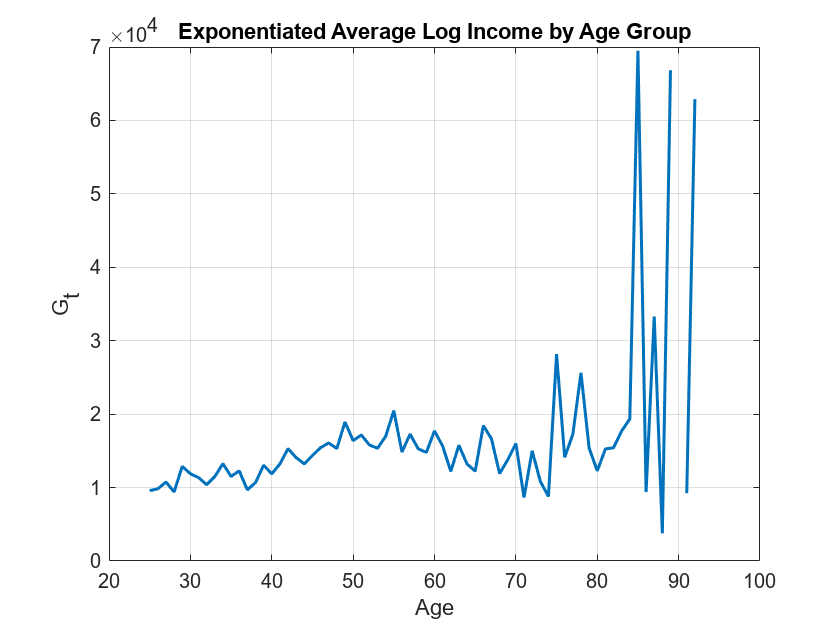

%% Plot Gt against age
figure;
plot(age_groups, Gt, '-', 'LineWidth', 1.5);
xlabel('Age');
ylabel('G_t');
title('Exponentiated Average Log Income by Age Group');
grid on;
saveas(gcf, fullfile(figout, 'gt.png'));

## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 1.3438 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

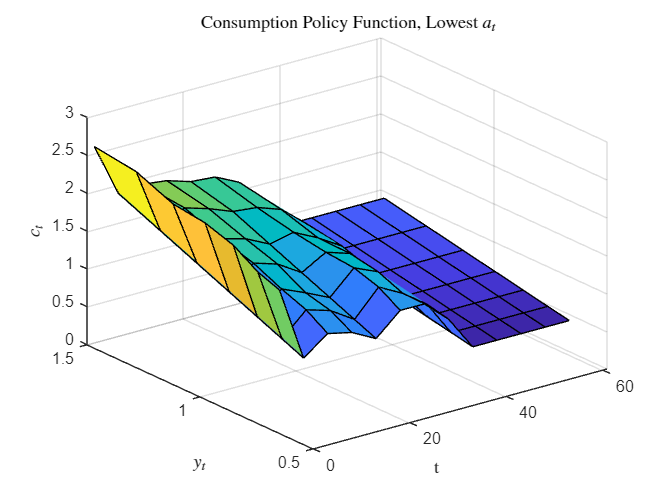

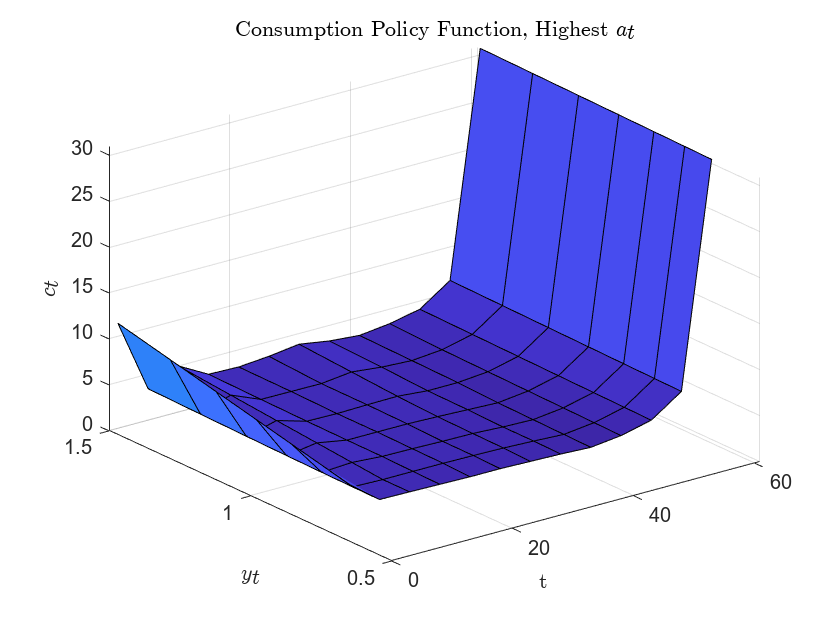

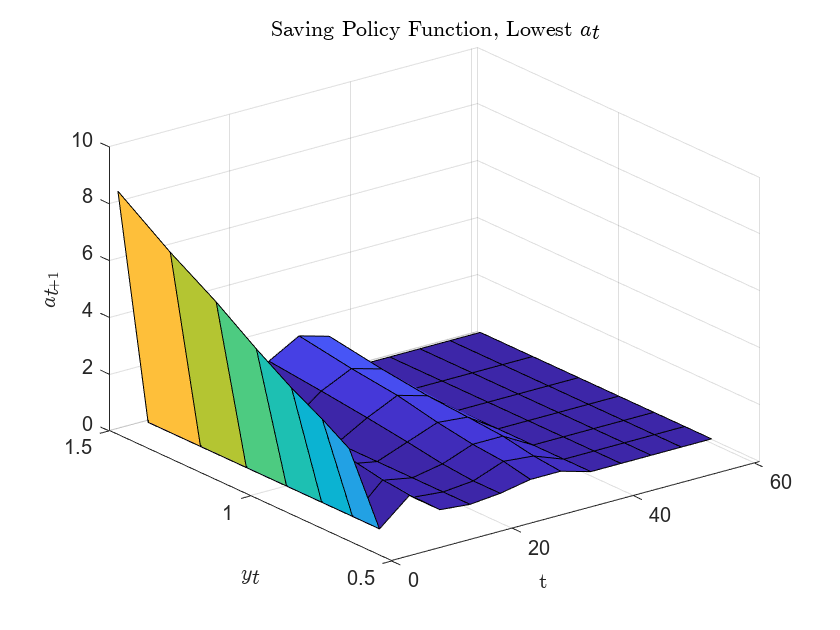

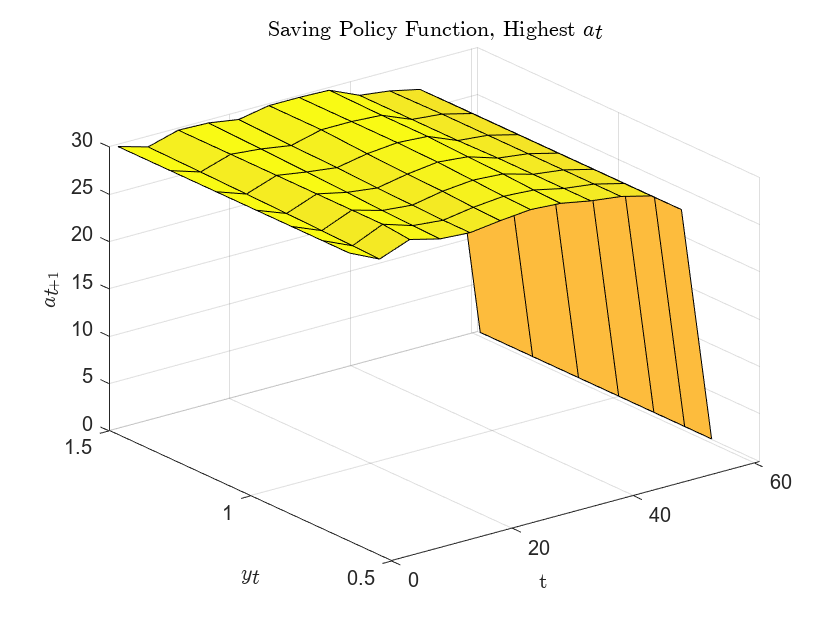

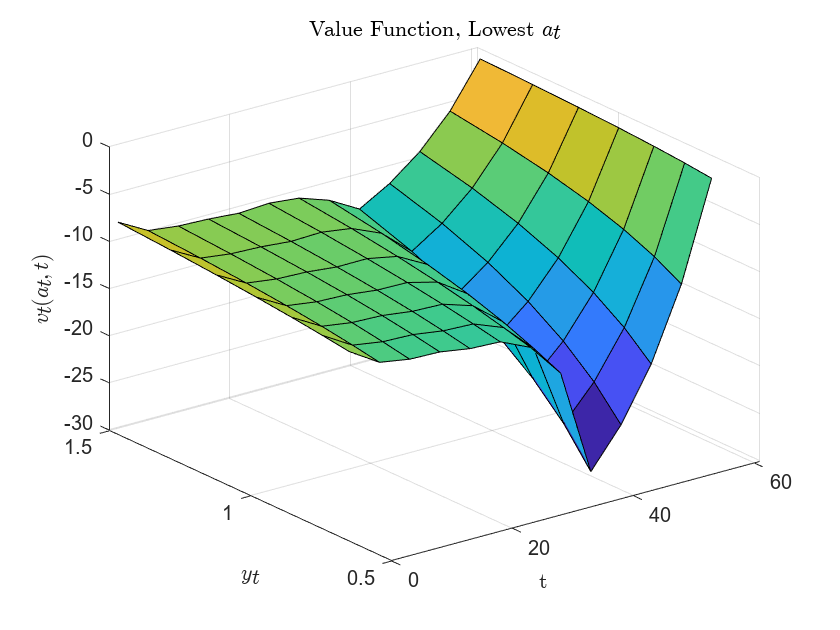

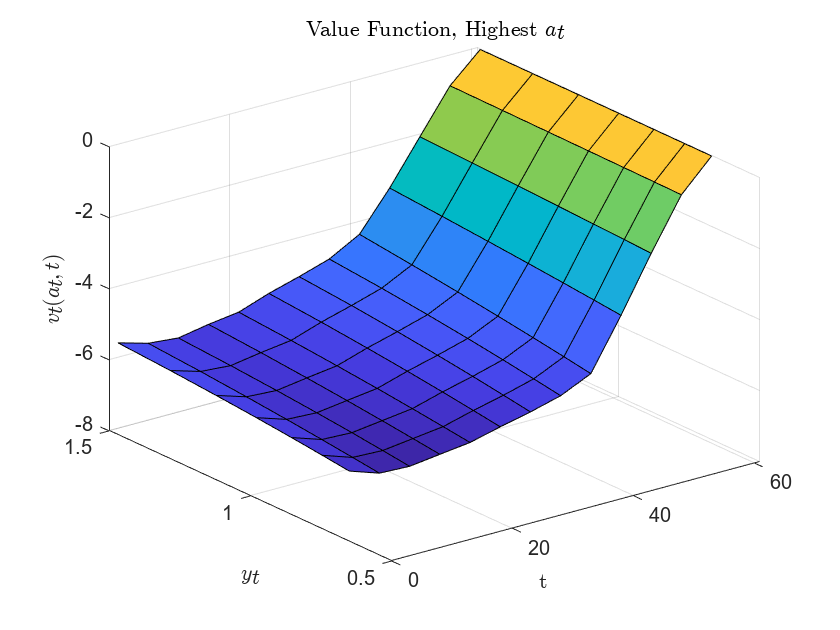

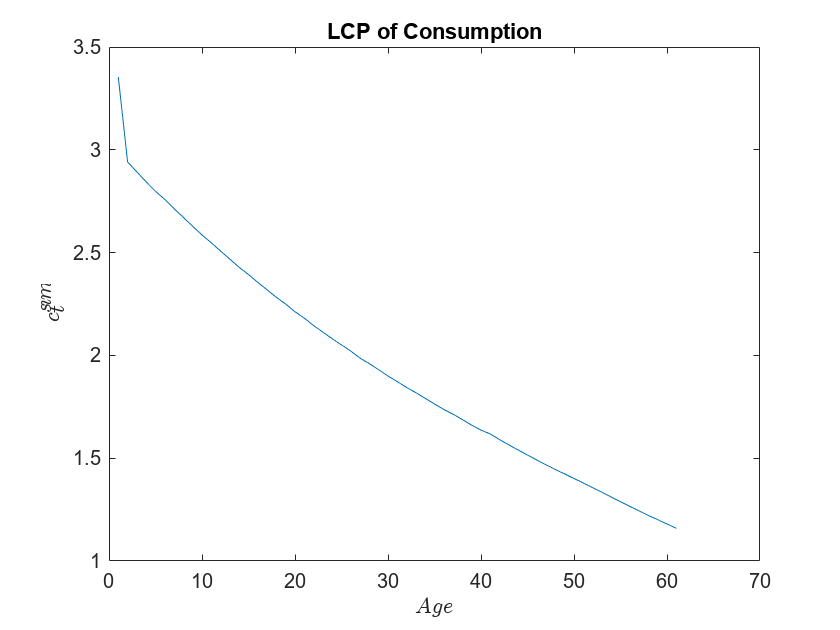

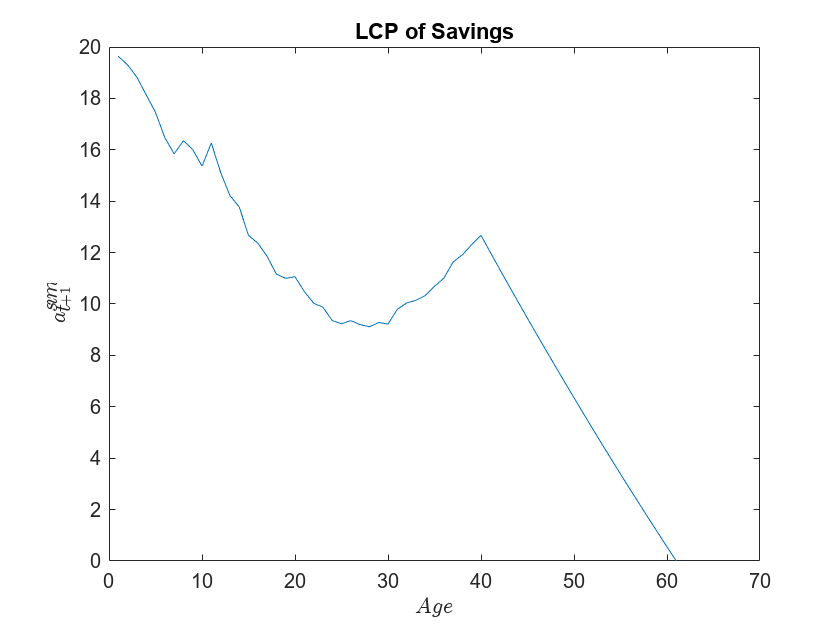

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim, figout) % Plot the model functions and time series.

## Simulate the model for different values of  $\beta$ and  $\gamma$

%% Run Scenarios 
% Define parameter values
betas = [0.90, 0.92, 0.94, 0.96];

% Create figure with 2 subplots
figure;
colors = lines(length(betas));

% Initialize storage for all lines
cons_data = nan(length(betas), 100); % Assuming T ≤ 100
asset_data = nan(length(betas), 100);
T_max = 0;

for i = 1:length(betas)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = betas(i);
    par.gamma = 2.00;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    % Initialize storage
    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    % Store data for plotting
    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


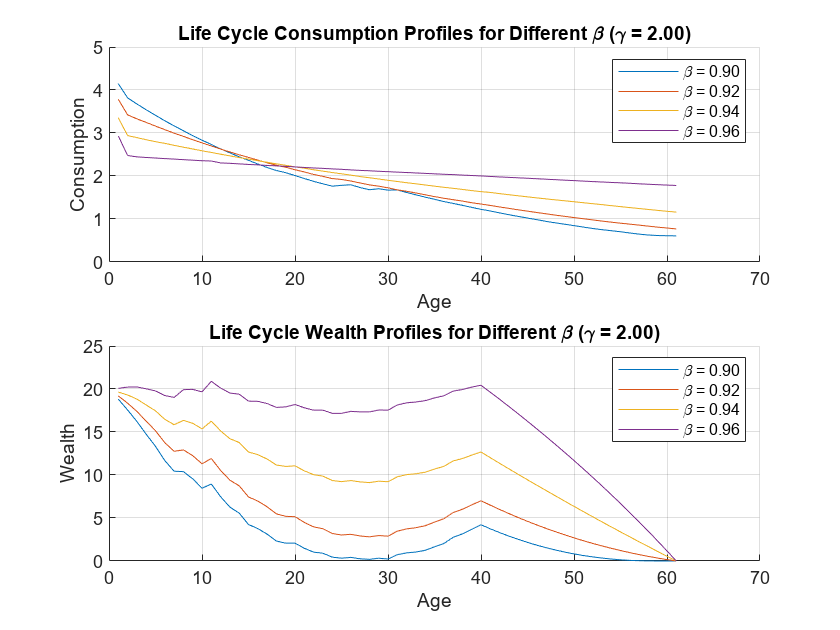

%% Subplot 1: Consumption
subplot(2,1,1);
hold on;
for i = 1:length(betas)
    plot(1:T_max, cons_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\beta = %.2f', betas(i)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \beta (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(2,1,2);
hold on;
for i = 1:length(betas)
    plot(1:T_max, asset_data(i,1:T_max), 'Color', colors(i,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\beta = %.2f', betas(i)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \beta (\gamma = 2.00)');
legend('show', 'Location', 'best');
grid on;
hold off;
saveas(gcf, fullfile(figout, 'sim1.png'))

%% Plot life cycle profiles for different gamma values
gammas = [2.00, 3.00, 4.00, 5.00];

% Create figure with 2 subplots
figure;
colors = lines(length(gammas));

% Storage for max age
T_max = 0;
cons_data = nan(length(gammas), 100); % Assuming max T ≤ 100
asset_data = nan(length(gammas), 100);

for j = 1:length(gammas)
    par = model.setup;
    par = model.gen_grids(par); 
    par.gamma = gammas(j);
    par.beta = 0.96;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


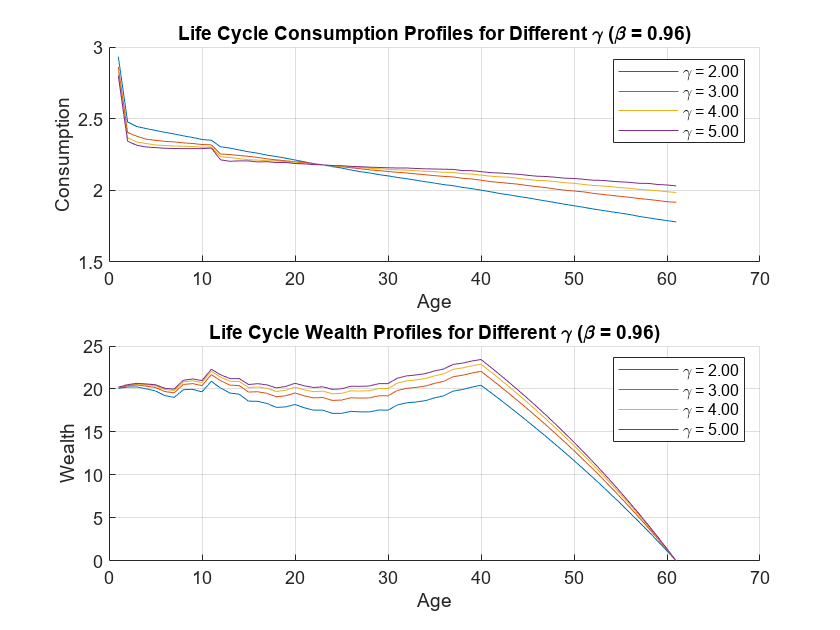

%% Subplot 1: Consumption
subplot(2,1,1);
hold on;
for j = 1:length(gammas)
    plot(1:T_max, cons_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gammas(j)));
end
xlabel('Age');
ylabel('Consumption');
title('Life Cycle Consumption Profiles for Different \gamma (\beta = 0.96)');
legend('show', 'Location', 'best');
grid on;
hold off;

%% Subplot 2: Wealth
subplot(2,1,2);
hold on;
for j = 1:length(gammas)
    plot(1:T_max, asset_data(j,1:T_max), 'Color', colors(j,:), ...
        'LineStyle', '-', 'DisplayName', sprintf('\\gamma = %.2f', gammas(j)));
end
xlabel('Age');
ylabel('Wealth');
title('Life Cycle Wealth Profiles for Different \gamma (\beta = 0.96)');
legend('show', 'Location', 'best');
grid on;
hold off;
saveas(gcf, fullfile(figout, 'sim2.png'))


%% Compute and plot heatmap of average simulated wealth
avg_wealth = nan(length(betas), length(gammas)); % Ensure NaN initialization

for i = 1:length(betas)
    for j = 1:length(gammas)
        % Initialize and update parameters
        par = model.setup;
        par = model.gen_grids(par);
        par.beta = betas(i);
        par.gamma = gammas(j);

        % Solve model for given parameters
        sol = solve.lc(par);
        sim = simulate.lc(par, sol);

        % Compute average wealth
        avg_wealth(i,j) = mean(sim.asim(:), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

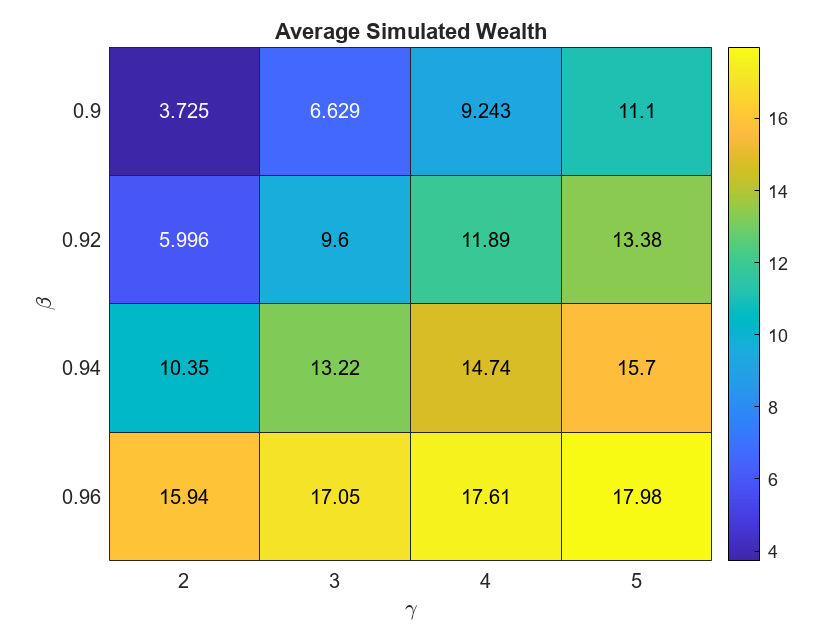

% Create heatmap
figure;
h = heatmap(string(gammas), string(betas), avg_wealth, 'Colormap', parula);
xlabel('\gamma');
ylabel('\beta');
title('Average Simulated Wealth');
saveas(gcf, fullfile(figout, 'sim3.png'))

### Descriptive Statistics for comparison of different values of $\beta$ and  $\gamma$

%% Define parameter values
betas = [0.90, 0.92, 0.94, 0.96];
gammas = [2.00, 3.00, 4.00, 5.00];

% Initialize storage for all data
cons_data = nan(length(betas), 100);  % Assuming T_max ≤ 100
asset_data = nan(length(betas), 100);
T_max = 0;

% Initialize structure for storing descriptive statistics
descriptive_stats = struct();

%% Loop over different betas to calculate consumption and wealth
for i = 1:length(betas)
    par = model.setup;
    par = model.gen_grids(par); 
    par.beta = betas(i);
    par.gamma = 2.00;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        lcp_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
        lcp_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    cons_data(i,1:par.T) = lcp_c;
    asset_data(i,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(i, 1:T_max), 'omitnan');
    cons_std = std(cons_data(i, 1:T_max), 'omitnan');
    cons_min = min(cons_data(i, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(i, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(i, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.beta(i).cons_mean = cons_mean;
    descriptive_stats.beta(i).cons_std = cons_std;
    descriptive_stats.beta(i).cons_min = cons_min;
    descriptive_stats.beta(i).cons_max = cons_max;
    descriptive_stats.beta(i).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(i, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(i, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(i, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(i, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.beta(i).wealth_mean = wealth_mean;
    descriptive_stats.beta(i).wealth_std = wealth_std;
    descriptive_stats.beta(i).wealth_min = wealth_min;
    descriptive_stats.beta(i).wealth_max = wealth_max;
    descriptive_stats.beta(i).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



%% Display Descriptive Statistics for Consumption
cons_table = table();
cons_table.Beta = betas';
cons_table.Mean = [descriptive_stats.beta(:).cons_mean]';
cons_table.StdDev = [descriptive_stats.beta(:).cons_std]';
cons_table.Min = [descriptive_stats.beta(:).cons_min]';
cons_table.Max = [descriptive_stats.beta(:).cons_max]';
cons_table.Median = [descriptive_stats.beta(:).cons_median]';

disp('Descriptive Statistics for Consumption:');

Descriptive Statistics for Consumption:


disp(cons_table);

    Beta     Mean     StdDev       Min       Max      Median
    ____    ______    _______    _______    ______    ______

     0.9    1.7553    0.92819    0.60819    4.1466    1.6717
    0.92    1.8214    0.79312    0.76919    3.7835    1.6775
    0.94    1.9482    0.54338     1.1593     3.354    1.8724
    0.96     2.111    0.22344       1.78     2.933      2.09




%% Loop over different gammas to calculate consumption and wealth
cons_data = nan(length(gammas), 100);  % Reset storage for consumption data
asset_data = nan(length(gammas), 100);  % Reset storage for asset data
T_max = 0;

for j = 1:length(gammas)
    par = model.setup;
    par = model.gen_grids(par); 
    par.gamma = gammas(j);
    par.beta = 0.96;
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    T_max = max(T_max, par.T);

    lcp_c = nan(par.T,1);
    lcp_a = nan(par.T,1);

    for t = 1:par.T
        indices = (sim.tsim == t);
        lcp_c(t) = mean(sim.csim(indices), 'omitnan');
        lcp_a(t) = mean(sim.asim(indices), 'omitnan');
    end

    cons_data(j,1:par.T) = lcp_c;
    asset_data(j,1:par.T) = lcp_a;

    % Calculate descriptive statistics for consumption
    cons_mean = mean(cons_data(j, 1:T_max), 'omitnan');
    cons_std = std(cons_data(j, 1:T_max), 'omitnan');
    cons_min = min(cons_data(j, 1:T_max), [], 'omitnan');
    cons_max = max(cons_data(j, 1:T_max), [], 'omitnan');
    cons_median = median(cons_data(j, 1:T_max), 'omitnan');

    % Store statistics for consumption
    descriptive_stats.gamma(j).cons_mean = cons_mean;
    descriptive_stats.gamma(j).cons_std = cons_std;
    descriptive_stats.gamma(j).cons_min = cons_min;
    descriptive_stats.gamma(j).cons_max = cons_max;
    descriptive_stats.gamma(j).cons_median = cons_median;

    % Calculate descriptive statistics for wealth
    wealth_mean = mean(asset_data(j, 1:T_max), 'omitnan');
    wealth_std = std(asset_data(j, 1:T_max), 'omitnan');
    wealth_min = min(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_max = max(asset_data(j, 1:T_max), [], 'omitnan');
    wealth_median = median(asset_data(j, 1:T_max), 'omitnan');

    % Store statistics for wealth
    descriptive_stats.gamma(j).wealth_mean = wealth_mean;
    descriptive_stats.gamma(j).wealth_std = wealth_std;
    descriptive_stats.gamma(j).wealth_min = wealth_min;
    descriptive_stats.gamma(j).wealth_max = wealth_max;
    descriptive_stats.gamma(j).wealth_median = wealth_median;
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


%% Display Descriptive Statistics for Wealth
wealth_table = table();
wealth_table.Gamma = gammas';
wealth_table.Mean = [descriptive_stats.gamma(:).cons_mean]';
wealth_table.StdDev = [descriptive_stats.gamma(:).cons_std]';
wealth_table.Min = [descriptive_stats.gamma(:).cons_min]';
wealth_table.Max = [descriptive_stats.gamma(:).cons_max]';
wealth_table.Median = [descriptive_stats.gamma(:).cons_median]';

disp('Descriptive Statistics for Wealth:');

Descriptive Statistics for Wealth:


disp(wealth_table);

    Gamma     Mean     StdDev      Min       Max      Median
    _____    ______    _______    ______    ______    ______

      2       2.111    0.22344      1.78     2.933      2.09
      3      2.1432    0.16209    1.9168    2.8602     2.126
      4      2.1597    0.13223    1.9847    2.8212    2.1429
      5      2.1705    0.11405    2.0309    2.7993    2.1559



## Stochastic Life Cycle Model with Endogenous Labor

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{n_t\}_{t=0}^{T-1} ,\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} U =  \sum_{t=1}^{T-1} \beta^{t} \left[\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} \right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		G_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$, $G_t$ is age-specific average of income and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. Given an endowment of one unit of time, part of it can go to labor $n_t$ and the rest will go to leisure $l_t$. Consumers derive utility from leisure but must supply labor to produce the final good.

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, n_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma}  + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}}+  \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
	       G_t n_te^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


 $\begin{array}{r l} 1 = n_t + l_t \end{array} \$.

The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t, n_t) = \underset{a_{t+1}, n_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta V_{t+1}(a_{t+1},t+1,y_{t+1}) \ ,$$



$$y_t = \begin{cases}
		G_t n_t e^{(\rho \log y_{t-1} + \epsilon_t)} & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_t \geq 0,$$



$$a_0 \geq0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


$\begin{array}{r l} 1 = n_t + l_t \end{array} \$.

which reduces the choice space to $a_{t+1}$.

## Set the parameters and generate the state space.

Calls: model2.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

clc
clear
close all

par = model2.setup; % Set parameters.
par = model2.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve2.m, and model2.m.

Note that the allocation of labor and leisure is a static decision. From (5.23) in Adda and Cooper, the intratemporal is


$$(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} = -\gamma(1-n_t)^{\frac{1}{\nu}} \ .$$


We have pre-determined grids for $a_t$, and we use the same grid for $a_{t+1}$ as $a_t$. Given these and the equation above, we can $n_t$ by using a numerical solver to minimize


$$f(n_t) = (A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} + \gamma(1-n_t)^{\frac{1}{\nu}} \ ,$$


and obtain optimal labor supply given any combination of the state variables and any potential choice of $a_{t+1}$ associated with these. Crucially, we can do this outside of the value function iteration algorithm because the decision is static. Once we have the optimal $n_t$, we can treat this as a parameter for each combination of $k_t, k_{t+1},$ and $A_t$.

t = cputime;
sol = solve2.lc(par); % Solve the model using Value Function Iteration.
fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)

## Simulate the model and plot the model functions and time series.

Calls: simulate2.m and my_graph2.m.

sim = simulate2.lc(par,sol); % Simulate the model.
my_graph2.plot_policy(par,sol,sim) % Plot the model functions and time series.